Exercise 5.1

% k=0:15;
% L1=0:31;
% L2=0:63;
% L3=0:255;
% w0=(2*pi)/sqrt(17);
% 
% x=sin(w0*k);
% x_16=fft(x);
% x_32=fft(x,32);
% x_64=fft(x,64);
% x_256=fft(x,256);
% 
% subplot(2,2,1);
% plot(k/16,abs(x_16));hold on;
% xlim([0.0 15/16])
% xlabel('Normalized Frequency (\Omega/\pi)');
% ylabel('Magnitude');
% title('N = 16');
% stem(k/16,abs(x_16),'o');hold off;
% 
% subplot(2,2,2);
% plot(L1/32,abs(x_32));hold on;
% xlabel('Normalized Frequency (\Omega/\pi)');
% ylabel('Magnitude');
% title('N = 32');
% xlim([0.0 31/32])
% stem(k/16,abs(x_16),'o');hold off;
% 
% 
% subplot(2,2,3);
% plot(L2/64,abs(x_64));hold on;
% xlabel('Normalized Frequency (\Omega/\pi)');
% ylabel('Magnitude');
% title('N = 64');
% xlim([0.0 63/64])
% stem(k/16,abs(x_16),'o');hold off;
% 
% subplot(2,2,4);
% plot(L3/256,abs(x_256));hold on;
% xlabel('Normalized Frequency (\Omega/\pi)');
% ylabel('Magnitude');
% title('N = 256');
% xlim([0.0 255/256])
% stem(k/16,abs(x_16),'o');hold off;

Exercise 5.2

（a）

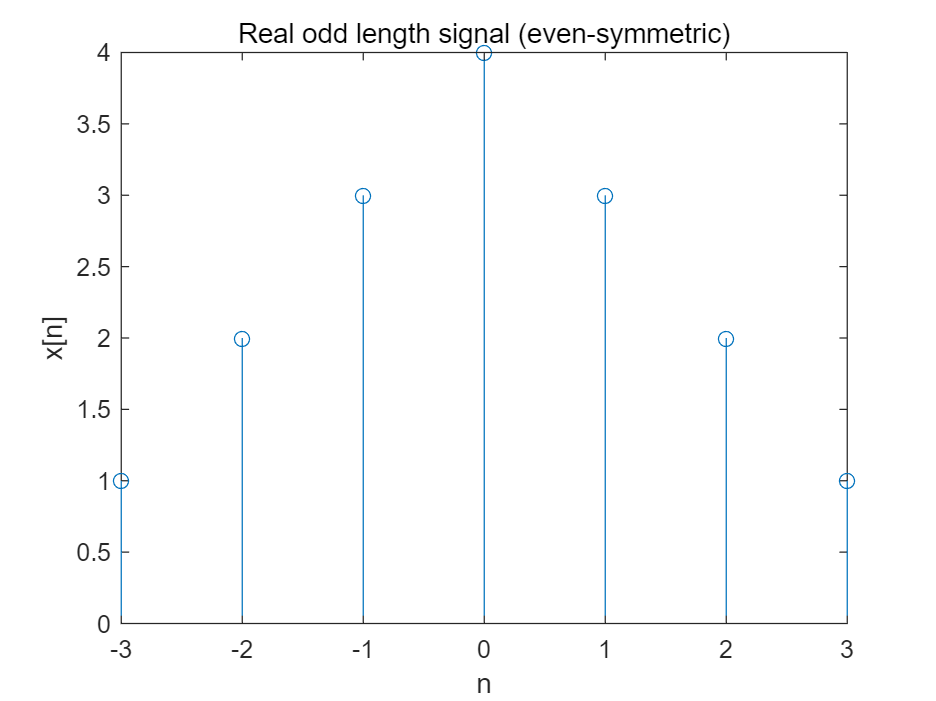

n=-3:3;
N=length(n);
x_o=[1 2 3 4 3 2 1];
x=[x_o((N+1)/2:N) x_o(1:(N-1)/2)];
stem(n,x_o);

xlabel('n'),ylabel('x[n]');
title('Real odd length signal (even-symmetric)');

% stem(n,x);
% xlabel('n'),ylabel('x[n]');
% title('test signal (after a time shift)');
x_DFT=fft(x);
x1=fftshift(x_DFT);
% subplot(3,1,1);
% plot(n,abs(x1));hold on;
% stem(n,abs(x1),'o');
% ylabel('Magnitude');
% title('DFT with N = 7');hold off;
% 
% subplot(3,1,2);
% stem(n,real(x1));title('real part');
% ylabel('Magnitude');
% 
% subplot(3,1,3);
% stem(n,imag(x1)); title('imaginary part');
% xlabel('k');
% ylabel('Magnitude');

 (b)

N2=3*N;
% x_FFT=fft(x,N2);
% x2=fftshift(x_FFT);
L2=-(N2-1)/2:(N2-1)/2;
% subplot(3,1,1);
% plot(L2,abs(x2));hold on;
% xlabel('k');
% ylabel('Magnitude');
% title('DFT (Length = 3\times N_1) ');hold off;
% subplot(3,1,2);
% stem(L2,real(x2));title('real of FFT');
% xlabel('k');
% ylabel('Magnitude');
% subplot(3,1,3);
% stem(L2,imag(x2));title('imaginary of FFT');
% xlabel('k');
% ylabel('Magnitude');

（c）

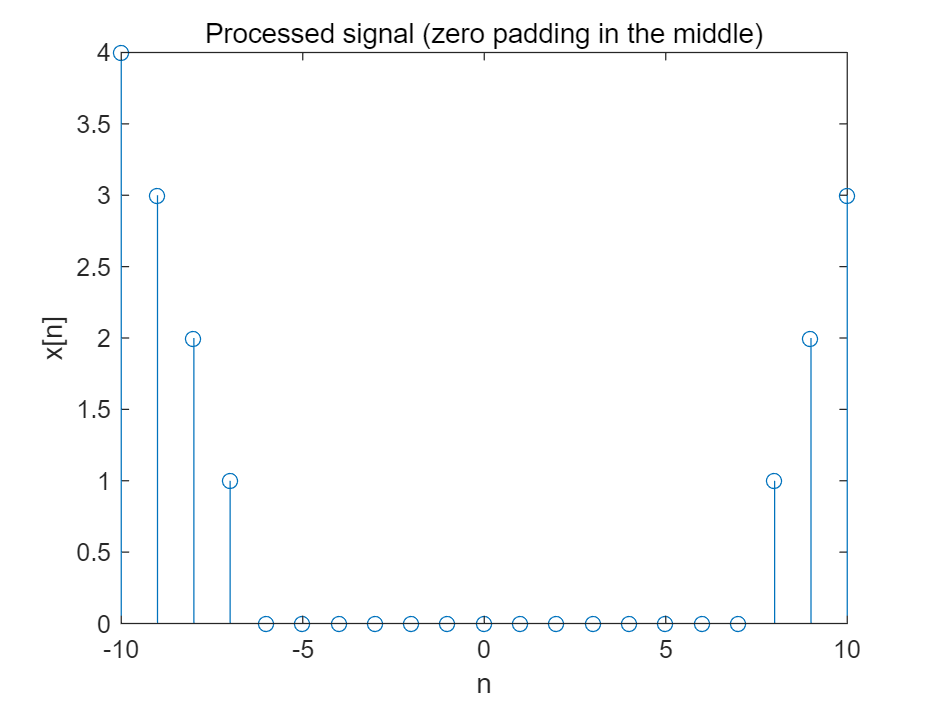

% % x_middle=middle(x,N);
a=(N+1)/2;
x_middle=[x(1:a) zeros(1,2*N) x(a+1:N)];
stem(L2,x_middle);
xlabel('n'),ylabel('x[n]');
title('Processed signal (zero padding in the middle)');

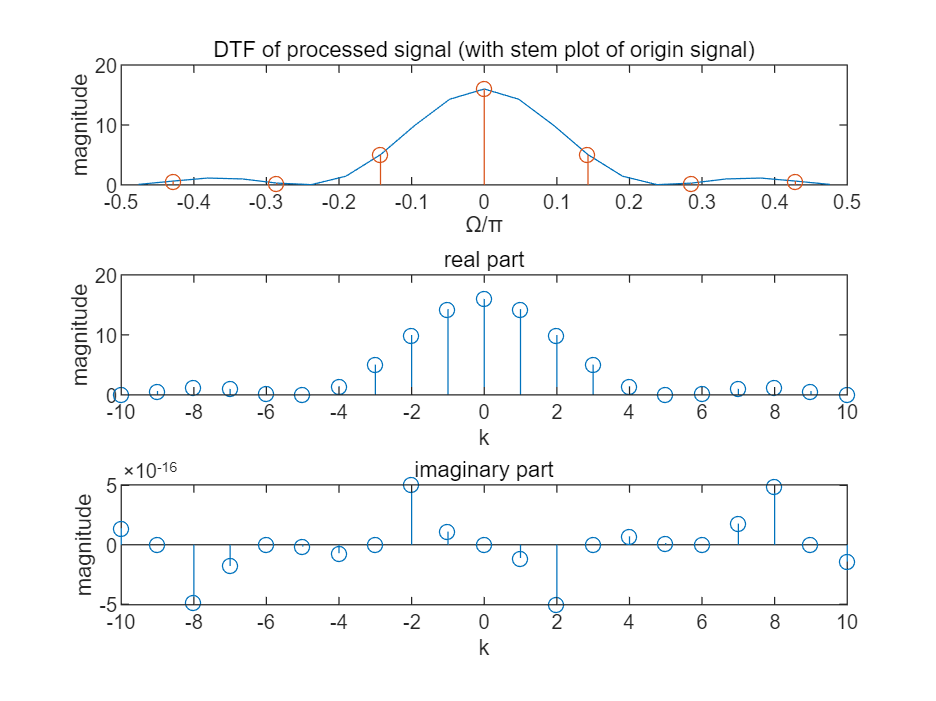

x_DFT_middle=fft(x_middle);
x3=fftshift(x_DFT_middle);
subplot(3,1,1);
plot(L2/N2,abs(x3));hold on;
stem(n/N,abs(x1),'o');
xlabel('\Omega/\pi');
ylabel('magnitude');
title('DTF of processed signal (with stem plot of origin signal)');hold off;
subplot(3,1,2);
stem(L2,real(x3));title('real part');
xlabel('k');
ylabel('magnitude');
subplot(3,1,3);
stem(L2,imag(x3));title('imaginary part');
xlabel('k');
ylabel('magnitude');